ЛАБОРАТОРНА РОБОТА №5

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

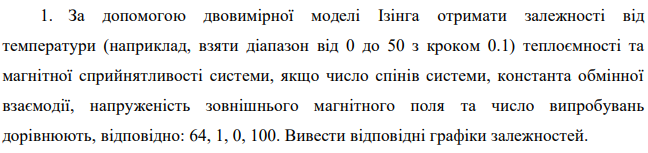

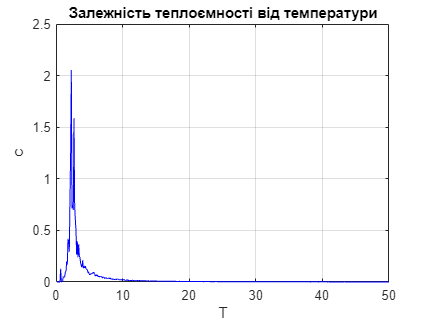

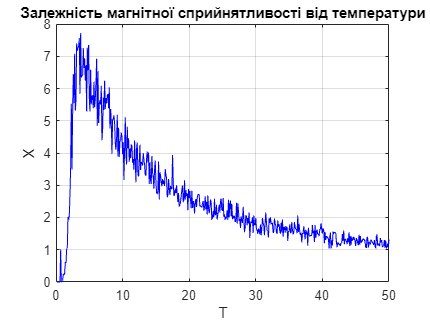

clearvars;
Nspin=64; % число спінів системи
J=1; % константа обмінної взаємодії
h=0; % зовнішнє поле
Esi=-10; % задання кінцевого значення енергії системи
NTrial=100; % кількість випробувань
% обчислення миттєвих значень: повної енергії системи (Es), енергії демона (Ed),
% намагніченості (SpM) та середнього числа прийняття рішень (Accept)

modelIzing2(64,1,0,[0:0.1:50],100);

function modelIzing2(Nspin,J,h,TT,NTrial)
% Функція, що повертає миттєві значення: Es - повної енергії системи,
% Ed - енергії демона, SpM - намагніченості, Accept - середнього числа прийняття
% Nspin - число спінів системи, J - константа обмінної взаємодії
% h - зовнішнє магнітне поле, Esi - кінцева енергія системи
% NTrial - кількість випробувань задання конфігурації спінів в момент часу t=0
for i=1:length(TT)
    [Estart,Sstart,Mstart]=InitSp(Nspin,J,h);

    [E,Accept,M,S]=IsingKA(Nspin,J,h,NTrial,TT(i),Sstart,Mstart,Estart);

    j=1:length(E)-2000;
    E1(j)=E(j+2000);
    M1(j)=M(j+2000);

    E2=E1.^2;
    c(i)=(1/TT(i).^2)*(mean(E2)-mean(E1).^2)/Nspin;
    M2=M1.^2;
    x(i)=(1/TT(i))*(mean(M2)-mean(M1).^2);

end
figure(); plot(TT,c,'b'); grid; title('Залежність теплоємності від температури'); xlabel('\itT'); ylabel("\itc");
figure(); plot(TT,x,'b'); grid; title('Залежність магнітної сприйнятливості від температури'); xlabel('\itT'); ylabel("\itX");
end

function [E,s,M]=InitSp(Nspin,J,h)
% Функція, що повертає: Е - енергію системи, 
% M - значення повного магнітного момента,
% s - матрицю, що містить інформацію про конфігурацію системи в момент часу t=0
% Nspin - число спінів системи, J - константа обмінної взаємодії
% h - напруженість зовнішнього магнітного поля
Ns=Nspin.^0.5; M=0;
for i=1:Ns
    for j=1:Ns
    s(i,j)=1; M=M+s(i,j);
    end
end
E=Espin(Nspin,s,h,J);
end

function z=Espin(Nspin,s,h,J)
% Функція, що повертає енергію заданої конфігурації спінів,
% Nspin - число спінів системи, 
% s - матриця, що містить інформацію про розміщення спінів
% h - напруженість зовнішнього магнітного поля, J - константа обмінної взаємодії
Ns=Nspin.^0.5; E=0;
for i=1:Ns
    for j=1:Ns % перевірка періодичних граничних умов
        if j==1
            Left=Ns;
        else
            Left=j-1;
        end
        if j==Ns
            Right=1;
        else
            Right=j+1;
        end
        if i==Ns
            Up=1;
        else
            Up=i+1;
        end
        if i==1
            Down=Ns;
        else
            Down=i-1;
        end
        E=E-s(i,j)*(h+J*(s(i,Left)+s(i,Right)+s(Down,j)+s(Up,j))); % енергія системи
    end
end
z=E;
end

function [E,Accept,M,S]=IsingKA(Nspin,J,h,NTrial,T,Sstart,Mstart,Estart)
% Функція, що повертає: Е - миттєві значення енергії системи, 
% Accept - число прийняття, М - миттєвий магнітний момент системи, 
% S - миттєві конфігурації спінів системи, Nspin - число спінів системи, 
% J - константа обмінної взаємодії, h - напруженість зовнішнього магнітного поля,
% NTrial - число випробувань, T - температура системи, 
% Sstart - матриця, що містить інформацію про орієнтацію спінів у момент часу t=0
% Mstart - значення магнітного моменту системи у момент часу t=0
% Estart - енергія системи в момент часу t = 0
Ns=Nspin.^0.5; M(1)=Mstart; S=Sstart; E(1)=Estart; s=Sstart; Accept=0; k=2;
for i=1:NTrial
    for j=1:Nspin % випадковий вибір номера вузла для перекидання спіна
        Ix=floor(Ns*rand(1)+1); Iy=floor(Ns*rand(1)+1);
         % перевірка періодичних граничних умов
        if Ix==1
            Left=Ns;
        else
            Left=Ix-1;
        end
        if Ix==Ns
            Right=1;
        else
            Right=Ix+1;
        end
        if Iy==Ns
            Up=1;
        else
            Up=Iy+1;
        end
        if Iy==1
            Down=Ns;
        else
            Down=Iy-1;
        end
        % пробний перекид спіна
        Temp=s(Iy,Ix); s(Iy,Ix)=-s(Iy,Ix); 
        de=2*s(Iy,Ix)*(h+J*(s(Iy,Left)+s(Iy,Right)+s(Down,Ix)+s(Up,Ix)));
        if or(de<=0,rand(1)<=exp(-de./T)) % пробний перекид спіна приймається
            Accept=Accept+1; E(k)=E(k-1)-de; M(k)=M(k-1)+2*s(Iy,Ix);
        else % пробний перекид спіна не приймається
            s(Iy,Ix)=Temp; E(k)=E(k-1); M(k)=M(k-1);
        end
        S=cat(3,S,s); k=k+1;
    end
end
Accept=Accept/(NTrial*Nspin); % середнє число прийняття
end